ข้อที่น่าจะทำได้ 1 6 8 9

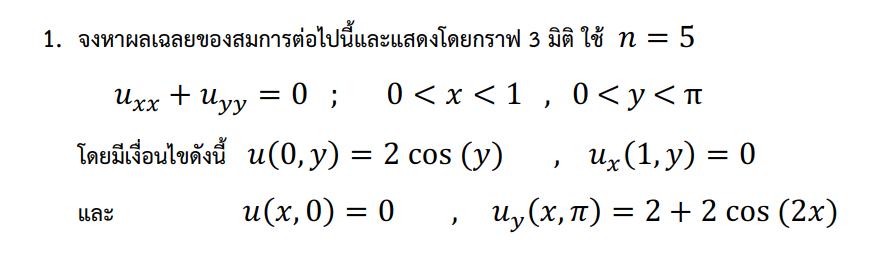

clear
clf
clc

syms x y u(x,y) phi(x) psi(x)
c = 1;
waveEq = -diff(u,x,2) == diff(u,y,2)

$$waveEq(x, y) = -\frac{\partial^{2}}{\partial x^{2}}u\left(x,y\right)=\frac{\partial^{2}}{\partial y^{2}}u\left(x,y\right)$$

cond1 = u(0,y) == 2*cos(y);
cond2 = diff(u(1,y),x) == 0;
cond3 = u(x,0) == 0;
cond4 = diff(u(x,pi),y) == 2+2*cos(2*x);

phi(x) = rhs(cond4) 

$$phi(x) = 2\,\cos\left(2\,x\right)+2$$

psi(x) = rhs(cond1)

$$psi(x) = 2\,\cos\left(y\right)$$

case 1 x>y

assume(x > y)
u1 = (phi(x-c*y)+phi(x+c*y))/2

$$u1 = \cos\left(2\,x-2\,y\right)+\cos\left(2\,x+2\,y\right)+2$$

u2 = int(psi,x,[x-c*y x+c*y])/(2*c)

$$u2 = 2\,y\,\cos\left(y\right)$$

u = simplify(u1+u2)

$$u = 2\,\cos\left(2\,x\right)\,\left(2\,{\cos\left(y\right)}^{2}-1\right)+2\,y\,\cos\left(y\right)+2$$

case 2 x<y

assume(x < y)
u1 = (-phi(-x-c*y)+phi(x+c*y))/2

$$u1 = 0$$

u2 = (int(-psi,x,[-x-c*y x+c*y])+int(psi,x,[x-c*y x+c*y]))/(2*c)

$$u2 = 2\,y\,\cos\left(y\right)-\cos\left(y\right)\,\left(2\,x+2\,y\right)$$

u = simplify(u1+u2)

$$u = -2\,x\,\cos\left(y\right)$$

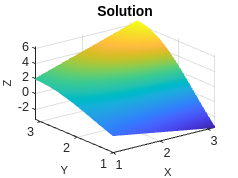


figure
fsurf(u,[1 pi],"EdgeColor","interp")
title("Solution")
xlabel('X','FontSize',8);
ylabel('Y',"FontSize",8);
zlabel('Z','FontSize',8);

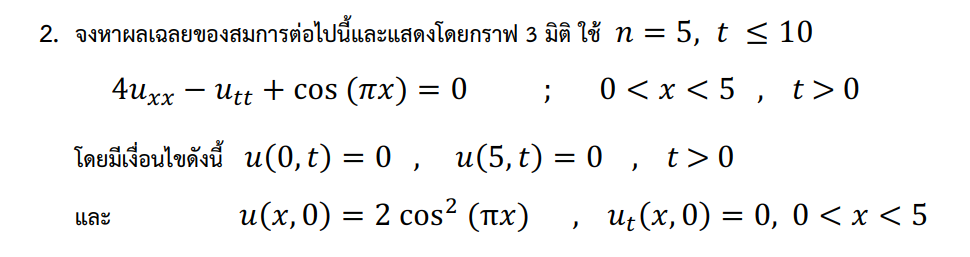

%nonhomo
clear
clc
clf
syms

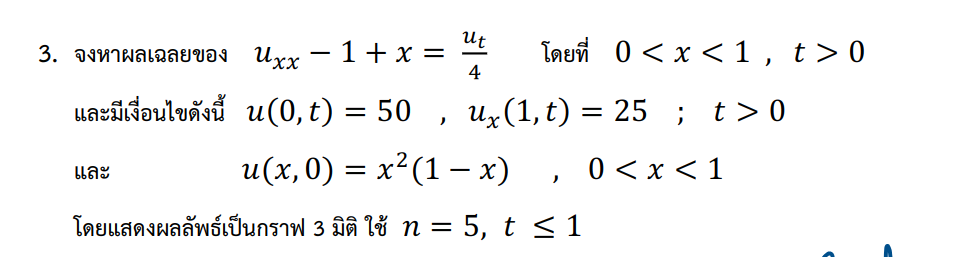

%nonhomo
clear
clf
clc
syms x t k r u(x,t) v(x,t) psi(x) f(x) n A(x) pi A_n
syms u_0 

Eq = diff(u,x,2)- 1 + x == diff(u,t,1)/4

$$Eq(x, t) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)+x-1=\frac{\frac{\partial }{\partial t}u\left(x,t\right)}{4}$$


assume(t,"positive")
cond1 = u(0,t) == 50;
cond2 = diff(u(1,t),x,1) == 25;
U = v(x,t) + psi(x)

$$U = \psi \left(x\right)+v\left(x,t\right)$$

sepvar = subs(Eq,u(x,t),U)

$$sepvar(x, t) = x+\frac{\partial^{2}}{\partial x^{2}}\psi \left(x\right)+\frac{\partial^{2}}{\partial x^{2}}v\left(x,t\right)-1=\frac{\frac{\partial }{\partial t}v\left(x,t\right)}{4}$$

var(x) = subs(sepvar,v(x,t),'V') 

$$var(x) = \frac{\partial^{2}}{\partial x^{2}}\psi \left(x\right)+x-1=0$$

eq = dsolve(var)

$$eq = C_{2}+\frac{x\,\left(-x^{2}+3\,x+C_{1}\right)}{6}$$

bcv0 = subs(cond1,u(0,t),v(0,t) + psi(0));
bcv1 = subs(cond2,u(1,t),v(1,t) + psi(1));
consPsi0 = subs(bcv0,v(0,t),0)

$$consPsi0 = \psi \left(0\right)=50$$

consPsi1 = subs(bcv1,v(1,t),0) 

$$consPsi1 = 0=25$$

eq = subs(eq,[sym('C1'),sym('C2')],[(r/(2*k))+u_0,0])

$$eq = \frac{x\,\left(u_{0}+3\,x+\frac{r}{2\,k}-x^{2}\right)}{6}$$

vx0 = f(x)- eq

$$vx0 = f\left(x\right)-\frac{x\,\left(u_{0}+3\,x+\frac{r}{2\,k}-x^{2}\right)}{6}$$

v(x,t) = symsum(A(n)*exp(-k*n^2*pi^2*t)*sin(n*pi*x),n,1,Inf)

$$v(x, t) = \sum_{n=1}^{\infty }\sin\left(n\,\pi \,x\right)\,{\mathrm{e}}^{-k\,n^{2}\,\pi^{2}\,t}\,A\left(n\right)$$

A_n = 2*int(v(x,0)*sin(n*pi*x),x,[0 1])

$$A\_n = 2\,\int_{0}^{1}\sin\left(n\,\pi \,x\right)\,\left(\sum_{n=1}^{\infty }\sin\left(n\,\pi \,x\right)\,A\left(n\right)\right)\mathrm{d}x$$

u = eq + v(x,t)

$$u = \frac{x\,\left(u_{0}+3\,x+\frac{r}{2\,k}-x^{2}\right)}{6}+\left(\sum_{n=1}^{\infty }\sin\left(n\,\pi \,x\right)\,{\mathrm{e}}^{-k\,n^{2}\,\pi^{2}\,t}\,A\left(n\right)\right)$$



v(x,t) = symsum(A(n)*exp(-k*n^2*pi^2*t)*sin(n*pi*x),n,1,5)

$$v(x, t) = A\left(1\right)\,{\mathrm{e}}^{-k\,\pi^{2}\,t}\,\sin\left(\pi \,x\right)+A\left(2\right)\,{\mathrm{e}}^{-4\,k\,\pi^{2}\,t}\,\sin\left(2\,\pi \,x\right)+A\left(3\right)\,{\mathrm{e}}^{-9\,k\,\pi^{2}\,t}\,\sin\left(3\,\pi \,x\right)+A\left(4\right)\,{\mathrm{e}}^{-16\,k\,\pi^{2}\,t}\,\sin\left(4\,\pi \,x\right)+A\left(5\right)\,{\mathrm{e}}^{-25\,k\,\pi^{2}\,t}\,\sin\left(5\,\pi \,x\right)$$

A_n = 2*int(v(x,0)*sin(n*pi*x),x,[0 1])

u = eq + v(x,t)

$$u = \frac{x\,\left(u_{0}+3\,x+\frac{r}{2\,k}-x^{2}\right)}{6}+A\left(1\right)\,{\mathrm{e}}^{-k\,\pi^{2}\,t}\,\sin\left(\pi \,x\right)+A\left(2\right)\,{\mathrm{e}}^{-4\,k\,\pi^{2}\,t}\,\sin\left(2\,\pi \,x\right)+A\left(3\right)\,{\mathrm{e}}^{-9\,k\,\pi^{2}\,t}\,\sin\left(3\,\pi \,x\right)+A\left(4\right)\,{\mathrm{e}}^{-16\,k\,\pi^{2}\,t}\,\sin\left(4\,\pi \,x\right)+A\left(5\right)\,{\mathrm{e}}^{-25\,k\,\pi^{2}\,t}\,\sin\left(5\,\pi \,x\right)$$

k= 1

k = 1

r = 10

r = 10

u = subs(u,sym(u_0),1)

$$u = \frac{x\,\left(3\,x+\frac{r}{2\,k}-x^{2}+1\right)}{6}+A\left(1\right)\,{\mathrm{e}}^{-k\,\pi^{2}\,t}\,\sin\left(\pi \,x\right)+A\left(2\right)\,{\mathrm{e}}^{-4\,k\,\pi^{2}\,t}\,\sin\left(2\,\pi \,x\right)+A\left(3\right)\,{\mathrm{e}}^{-9\,k\,\pi^{2}\,t}\,\sin\left(3\,\pi \,x\right)+A\left(4\right)\,{\mathrm{e}}^{-16\,k\,\pi^{2}\,t}\,\sin\left(4\,\pi \,x\right)+A\left(5\right)\,{\mathrm{e}}^{-25\,k\,\pi^{2}\,t}\,\sin\left(5\,\pi \,x\right)$$

u = subs(u)

$$u = \frac{x\,\left(-x^{2}+3\,x+6\right)}{6}+A\left(1\right)\,{\mathrm{e}}^{-\pi^{2}\,t}\,\sin\left(\pi \,x\right)+A\left(2\right)\,{\mathrm{e}}^{-4\,\pi^{2}\,t}\,\sin\left(2\,\pi \,x\right)+A\left(3\right)\,{\mathrm{e}}^{-9\,\pi^{2}\,t}\,\sin\left(3\,\pi \,x\right)+A\left(4\right)\,{\mathrm{e}}^{-16\,\pi^{2}\,t}\,\sin\left(4\,\pi \,x\right)+A\left(5\right)\,{\mathrm{e}}^{-25\,\pi^{2}\,t}\,\sin\left(5\,\pi \,x\right)$$

so(x,t) = symfun(u,[x t])

$$so(x, t) = \frac{x\,\left(-x^{2}+3\,x+6\right)}{6}+A\left(1\right)\,{\mathrm{e}}^{-\pi^{2}\,t}\,\sin\left(\pi \,x\right)+A\left(2\right)\,{\mathrm{e}}^{-4\,\pi^{2}\,t}\,\sin\left(2\,\pi \,x\right)+A\left(3\right)\,{\mathrm{e}}^{-9\,\pi^{2}\,t}\,\sin\left(3\,\pi \,x\right)+A\left(4\right)\,{\mathrm{e}}^{-16\,\pi^{2}\,t}\,\sin\left(4\,\pi \,x\right)+A\left(5\right)\,{\mathrm{e}}^{-25\,\pi^{2}\,t}\,\sin\left(5\,\pi \,x\right)$$

%

figure
fsurf(u,[-10 10],"EdgeColor","interp")

Error using fsurf
Input must be a function or functions of two variables.

title("Solution")
xlabel('X','FontSize',8);
ylabel('Y','FontSize',8);
zlabel('Z','FontSize',8)

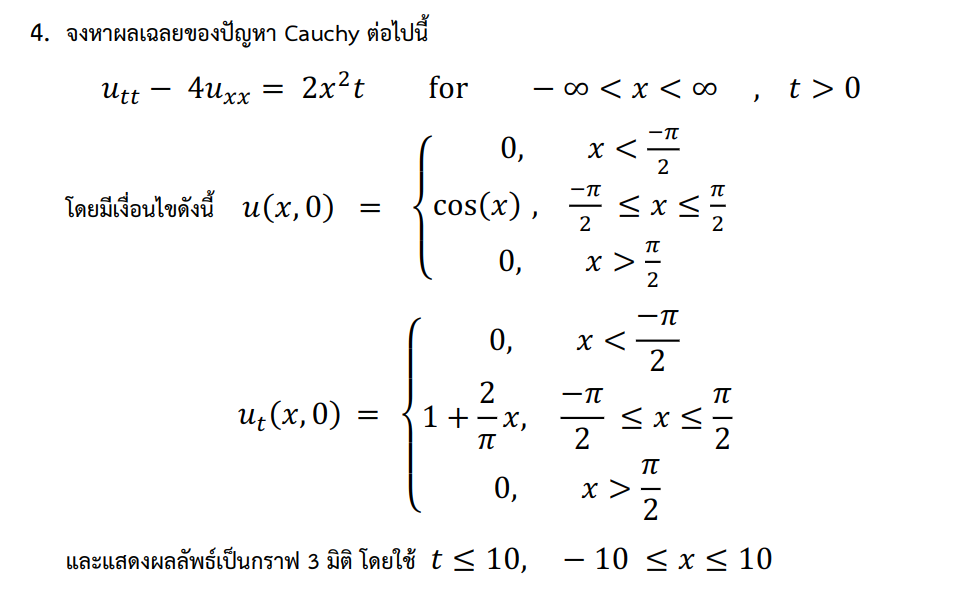

%nonhomo
clf
clear
clc

syms x t u(x,t) psi(x) phi(x)
c = 2;

Eq = diff(u,t,2)-c^2*diff(u,x,2) == 2*x^2*t

$$Eq(x, t) = \frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)-4\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=2\,t\,x^{2}$$

cond1 = u(x,0) == cos(x)

$$cond1 = u\left(x,0\right)=\cos\left(x\right)$$

cond2 = diff(u(x,0),t) == 1+(2/pi)*x

$$Dt0 = 0=\frac{5734161139222659\,x}{9007199254740992}+1$$


phi(x) = rhs(cond1); psi(x) = rhs(cond2);
u1 = (phi(x-c*t)+phi(x+c*t))/2

$$u1 = \frac{\cos\left(2\,t+x\right)}{2}+\frac{\cos\left(2\,t-x\right)}{2}$$

u2 = int(psi,x,[x-c*t x+c*t])/(2*c)

$$u2 = \frac{t\,\left(5734161139222659\,x+9007199254740992\right)}{9007199254740992}$$

u = simplify(u1+u2)

$$u = t+\frac{5734161139222659\,t\,x}{9007199254740992}+\cos\left(2\,t\right)\,\cos\left(x\right)$$

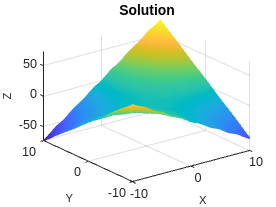


figure
fsurf(u,[-10 10],"EdgeColor","interp")
title("Solution")
xlabel('X','FontSize',8);
ylabel('Y','FontSize',8);
zlabel('Z','FontSize',8)

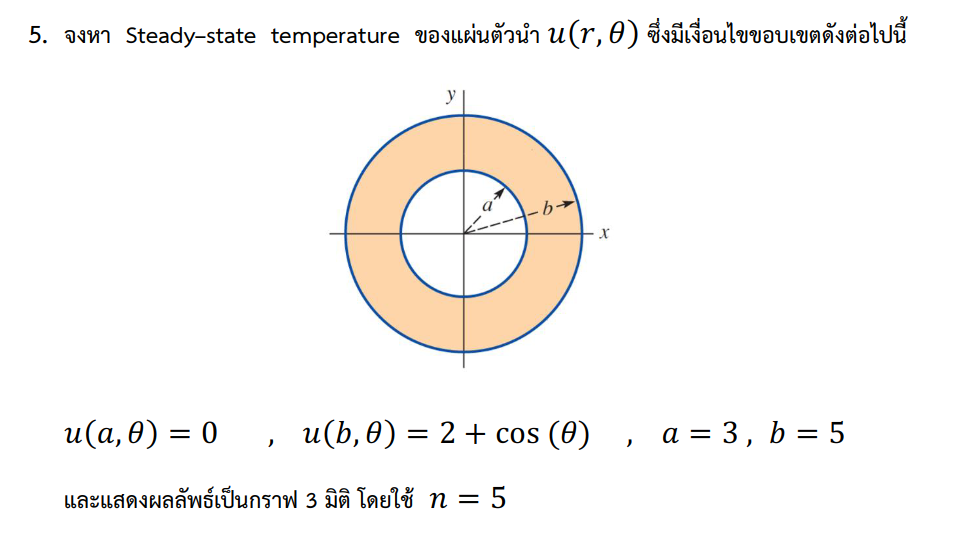

clear
clc
clf
syms u(a,phy)


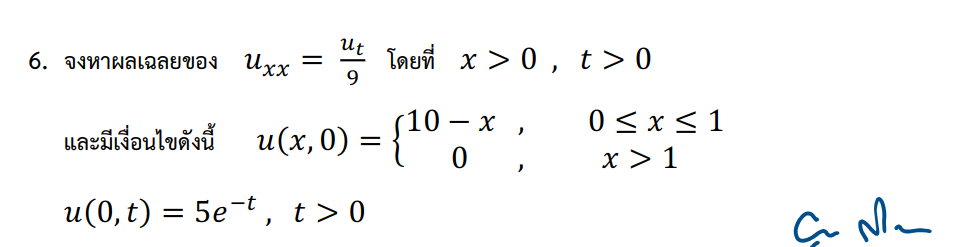

วัตถุยาว 1 หน่วย

ที่ x=0 steady state ความร้อนเป็น 0 

ที่เวลา 0   ัตถร้อน 0-1 หลังความยาว 1 ไม่ร้อน

%heat Eq 
clear
clf
clc
syms x t u(x,t) a
syms k a T0 T1 h fx
assume(x,"positive")
assume(t,"positive")
Eq = diff(u,x,2) == diff(u,t)/9;
con1 = u(x,0) == 10-x;
con2 =  u(x,0) == 0;


conS1 = diff(u,t) == 0; %steady state condition 
conS2= subs(Eq,diff(u,t),0)

$$conS2(x, t) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=0$$


syms sol(x) A B
con1 = sol(0) == T0

$$con1 = \mathrm{sol}\left(0\right)=T_{0}$$

con2 = -k*diff(sol(a)) == h*(sol(a)-T1)

$$con2 = -k\,\frac{\partial }{\partial a}\mathrm{sol}\left(a\right)=-h\,\left(T_{1}-\mathrm{sol}\left(a\right)\right)$$


sol(x) = A*x + B

$$sol(x) = B+A\,x$$


Eq2 = T0 == subs(sol,x,0) % ตาม con1

$$Eq2(x) = T_{0}=B$$

B = solve(Eq2,B)%จัดรูปใน term B

$$B = T_{0}$$

sol = subs(sol) 

$$sol(x) = T_{0}+A\,x$$

Eq3 = subs(con2)

$$Eq3 = -A\,k=h\,\left(T_{0}-T_{1}+A\,a\right)$$

A = solve(Eq3,A)

$$A = -\frac{h\,\left(T_{0}-T_{1}\right)}{k+a\,h}$$

sol = subs(sol)

$$sol(x) = T_{0}-\frac{h\,x\,\left(T_{0}-T_{1}\right)}{k+a\,h}$$

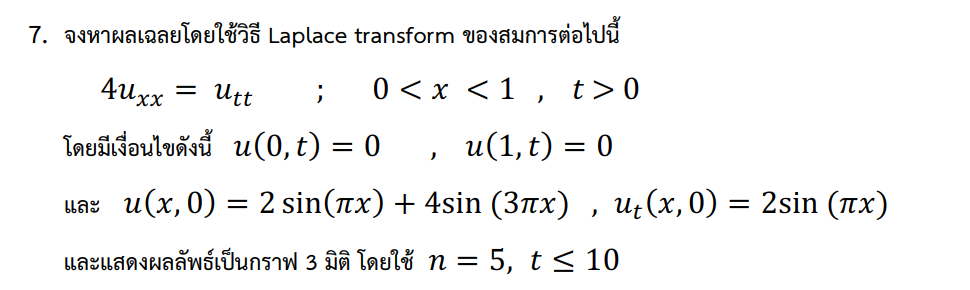

clear
clf
clc
syms x t s u(x,t) U(x,s) Y(x)
Dt = diff(u,t);
D2t = diff(Dt,t);
D2x = diff(u,x,2);
eqn = laplace(D2t == 4*D2x,t,s);
cond1 = u(0,t) == 0;
cond2 = u(1,t) == 0;

u(x,0) == 2*sin(pi*x)+4*sin(3*pi*x);
Dt(x,0) == 2*sin(pi*x)

$$ans = \left({\left(\frac{\partial }{\partial t}u\left(x,t\right)\right)|}_{t=0}\right)=2\,\sin\left(\pi \,x\right)$$

eqn = subs(eqn,{laplace(u,t,s),u(x,0),Dt(x,0),laplace(D2x,t,s)},{U(x,s),0,sin(pi*x),subs(D2x,{u,t},{U,s})})

$$eqn(x) = s^{2}\,U\left(x,s\right)-\sin\left(\pi \,x\right)=4\,\frac{\partial^{2}}{\partial x^{2}}U\left(x,s\right)$$

cond1 = laplace(cond1,t,s);
cond2 = laplace(cond2,t,s);

cond1 = subs(cond1,laplace(u(0,t),t,s),U(0,s))

$$cond1 = U\left(0,s\right)=0$$

cond2 = subs(cond2,laplace(u(1,t),t,s),U(1,s))

$$cond2 = U\left(1,s\right)=0$$


eqn_n = subs(eqn,U,Y)

$$eqn\_n(x) = s^{2}\,Y\left(x\right)-\sin\left(\pi \,x\right)=4\,\frac{\partial^{2}}{\partial x^{2}}Y\left(x\right)$$

cond_1 = subs(cond1,U,Y);
cond_2 = subs(cond2,U,Y);

sol_g = dsolve(eqn_n)

$$sol\_g = \begin{array}{l} C_{1}\,{\mathrm{e}}^{-\frac{s\,x}{2}}+C_{2}\,{\mathrm{e}}^{\frac{s\,x}{2}}-\frac{\pi \,\cos\left(\pi \,x\right)-\frac{s\,\sin\left(\pi \,x\right)}{2}}{\sigma_{1}}+\frac{\pi \,\cos\left(\pi \,x\right)+\frac{s\,\sin\left(\pi \,x\right)}{2}}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=4\,s\,\left(\frac{s^{2}}{4}+\pi^{2}\right) \end{array}$$

sol = dsolve(eqn_n,[cond_1 cond_2])

$$sol = \frac{\sin\left(\pi \,x\right)}{s^{2}+4\,\pi^{2}}$$

sol_t = ilaplace(sol,s,t)

$$sol\_t = \frac{\sin\left(2\,\pi \,t\right)\,\sin\left(\pi \,x\right)}{2\,\pi }$$

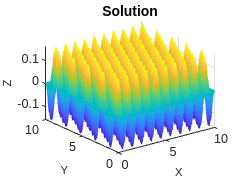


figure
fsurf(sol_t,[0 10],"EdgeColor","interp")
title("Solution")
xlabel('X','FontSize',8);
ylabel('Y',"FontSize",8)
zlabel('Z','FontSize',8)

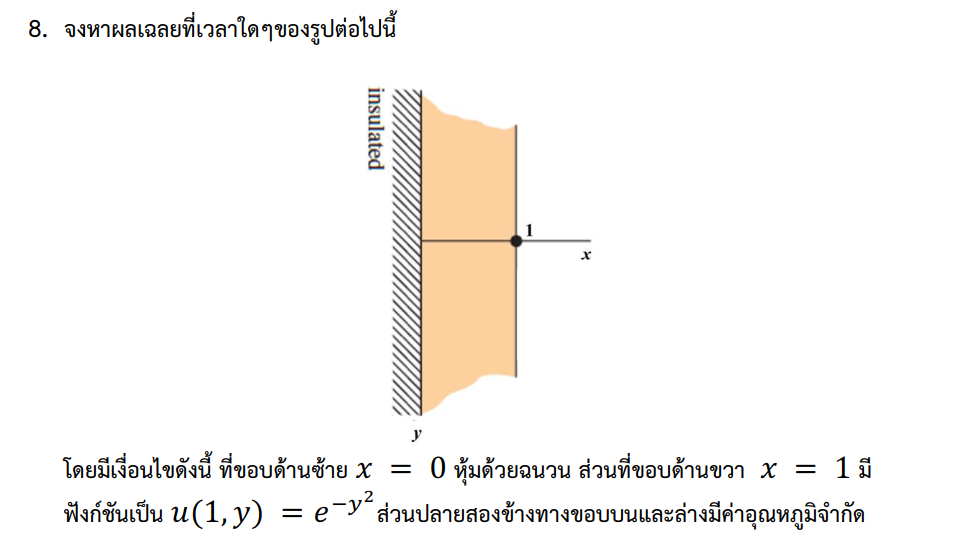

clear
clc
clf
syms



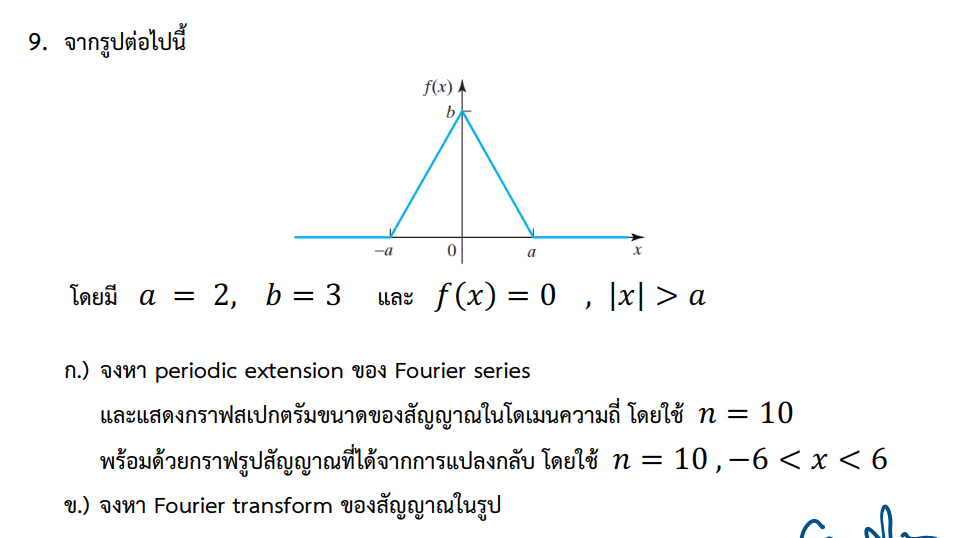

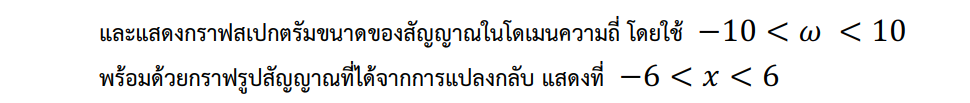

clear
clf
clc

T = 12;
fm = 4;
w0 = 2*pi/T;
syms t  

ft = -abs((3/2)*t)+3

$$ft = 3-\frac{3\,\left|t\right|}{2}$$


N = 10;%number of harmonic 
n = 1:N;

a0 = (2/T)*(int(ft,t,-2,2))

$$a0 = 1$$

when n is 1

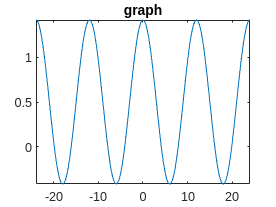

when n is 2

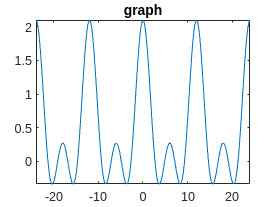

when n is 3

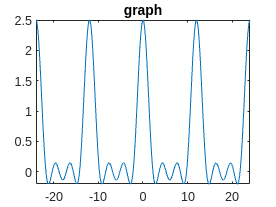

when n is 4

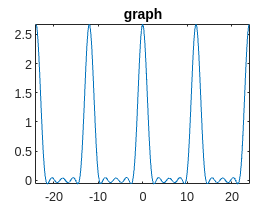

when n is 5

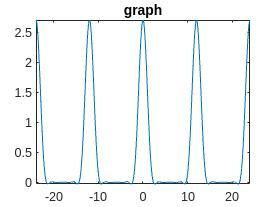

when n is 6

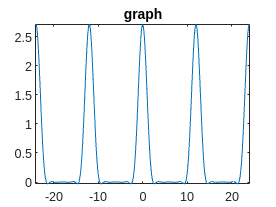

when n is 7

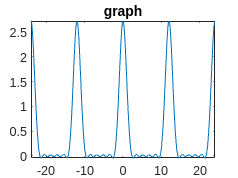

when n is 8

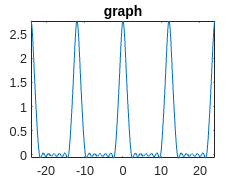

when n is 9

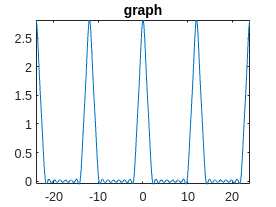

when n is 10

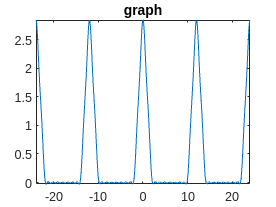

a_n = (2/T)*(int(ft*cos(2*pi*n*t/T),t,-2,2));
b_n = (2/T)*(int(ft*sin(2*pi*n*t/T),t,-2,2));

F = a0/2;

for i=1:N
    F = F+a_n(i)*cos(i*(2*pi/T)*t)+b_n(i)*sin(i*(2*pi/T)*t);
    figure;
    
    fprintf("when n is %d",i)
    fplot(F,[-T*2, T*2])
    title('graph')

end


%************************
fprintf("All of n")

All of n

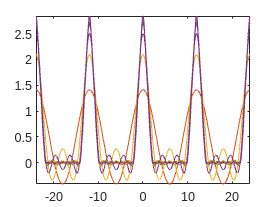

fplot(F,[-T*2, T*2])
F = a0/2;

for i=1:N
    F = F+a_n(i)*cos(i*(2*pi/T)*t)+b_n(i)*sin(i*(2*pi/T)*t);
    hold on
    fplot(F,[-T*2, T*2])
    hold off
    
end

%*************************
F

$$F = \frac{4\,\cos\left(\frac{\pi \,t}{2}\right)}{\pi^{2}}+\frac{27\,\cos\left(\frac{\pi \,t}{3}\right)}{4\,\pi^{2}}+\frac{27\,\cos\left(\frac{2\,\pi \,t}{3}\right)}{16\,\pi^{2}}+\frac{4\,\cos\left(\frac{3\,\pi \,t}{2}\right)}{9\,\pi^{2}}+\frac{9\,\cos\left(\frac{\pi \,t}{6}\right)}{\pi^{2}}+\frac{27\,\cos\left(\frac{4\,\pi \,t}{3}\right)}{64\,\pi^{2}}+\frac{27\,\cos\left(\frac{5\,\pi \,t}{3}\right)}{100\,\pi^{2}}+\frac{9\,\cos\left(\frac{5\,\pi \,t}{6}\right)}{25\,\pi^{2}}+\frac{9\,\cos\left(\frac{7\,\pi \,t}{6}\right)}{49\,\pi^{2}}+\frac{1}{2}$$

simplify(F)

$$ans = \begin{array}{l} \frac{97542144\,{\sigma_{1}}^{10}+80281600\,{\sigma_{1}}^{9}-205752960\,{\sigma_{1}}^{8}-172339200\,{\sigma_{1}}^{7}+137168640\,{\sigma_{1}}^{6}+125024256\,{\sigma_{1}}^{5}-19051200\,{\sigma_{1}}^{4}-24165120\,{\sigma_{1}}^{3}+1068480\,\sigma_{1}+352800\,\pi^{2}-3464937}{705600\,\pi^{2}}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{\pi \,t}{6}\right) \end{array}$$

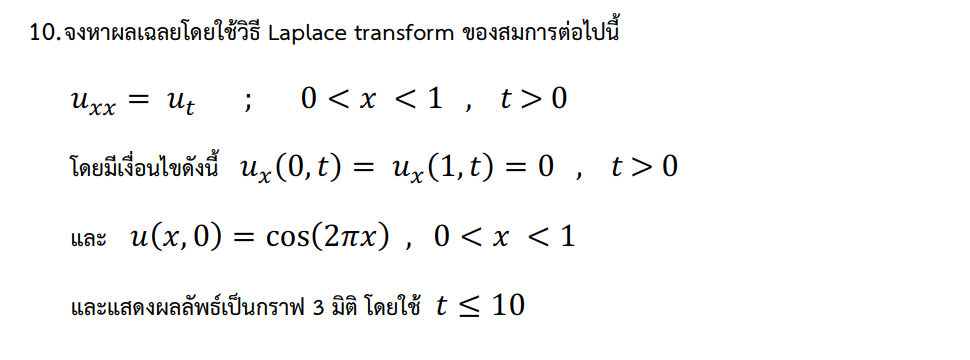

clear
clc
clf
syms x t s U(x, s)

pde = diff(U, x, 2) - diff(U, t);
laplace_pde = laplace(pde, t, s);

cond2 = subs(diff(U, x), x, 0) == 0; 
bc2 = subs(diff(U, x), x, 1) == 0; 

laplace_bc1 = laplace(cond2, t, s);
laplace_bc2 = laplace(bc2, t, s);
initial_condition = U(x, 0) == cos(2*pi*x);
laplace_initial_condition = laplace(initial_condition, t, s);

laplace_pde = subs(laplace_pde, laplace(U, t, s), U(x, s));
laplace_pde = subs(laplace_pde, laplace(diff(U, x), t, s), diff(U, x));
laplace_pde = subs(laplace_pde, [laplace_initial_condition, laplace_bc1, laplace_bc2]);
laplace_solution = solve(laplace_pde, U(x, s));

solution = ilaplace(laplace_solution, s, t);


Solution in the time domain:


disp(solution);

$$0$$

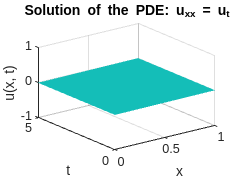

figure;
fsurf(solution, [0 1 0 5], 'EdgeColor', 'none');
title('Solution of the PDE: u_{xx} = u_t');
xlabel('x');
ylabel('t');
zlabel('u(x, t)');